clc
clear
close all
addpath('C:\Users\Alexey\OneDrive\QI\Qubits\Protocols');
addpath('C:\Users\Alexey\OneDrive\QI\Qubits\Tomography');
addpath('C:\Users\Alexey\OneDrive\QI\Qubits\Tomography\Kraus');

%% Начальное состояние
radius = 1;
tet = pi/4;
phi = 0;

po_1 = build_po_matrix(radius,tet,phi)

po_1 =     0.8536    0.3536
    0.3536    0.1464


[radius_1, tet_1, phi_1] = return_r_tet_phi_by_po_matrix(po_1)

radius_1 = 1.0000

tet_1 = 0.7854

phi_1 = 0


po_2 = build_po_matrix(radius,pi-tet,pi+phi)

po_2 =    0.1464 + 0.0000i  -0.3536 - 0.0000i
  -0.3536 + 0.0000i   0.8536 + 0.0000i


[radius_2, tet_2, phi_2] = return_r_tet_phi_by_po_matrix(po_2)

radius_2 = 1

tet_2 = 2.3562

phi_2 = 3.1416


r_1 = [radius_1*cos(phi_1)*sin(tet_1),...
       radius_1*sin(phi_1)*sin(tet_1),...
       radius_1*cos(tet_1)];
 
r_2 = [radius_2*cos(phi_2)*sin(tet_2),...
       radius_2*sin(phi_2)*sin(tet_2),...
       radius_2*cos(tet_2)];
 
p = 0.9;
po_3 = p * po_1 + (1 - p) * po_2;
trace(po_3)

ans = 1

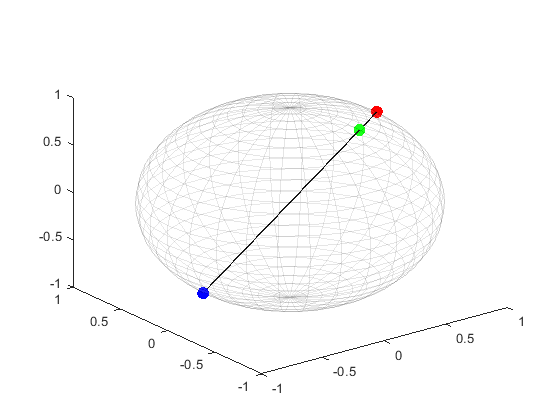


[radius_3, tet_3, phi_3] = return_r_tet_phi_by_po_matrix(po_3);

r_3 = [radius_3*cos(phi_3)*sin(tet_3),...
       radius_3*sin(phi_3)*sin(tet_3),...
       radius_3*cos(tet_3)];


%% Визуализация
type_cmap = 'white';
cmap = colormap(type_cmap);
hold on
[X,Y,Z] = sphere(30);
surf(X, Y, Z, 'EdgeAlpha', 0.1, 'FaceAlpha', 0.1);

scatter3(r_1(:,1), r_1(:,2), r_1(:,3), 80, 'r', 'filled');

scatter3(r_2(:,1), r_2(:,2), r_2(:,3), 80, 'b', 'filled');

scatter3(r_3(:,1), r_3(:,2), r_3(:,3), 80, 'g', 'filled');

plot3([r_1(:,1) r_2(:,1)],...
      [r_1(:,2) r_2(:,2)],...
      [r_1(:,3) r_2(:,3)],...
      'color', 'black', 'LineWidth', 1);
      
view(3)
hold off


phi0 = 1 / sqrt(2) * [1; 1];
phi1 = 1 / sqrt(2) * [1; -1];
p = 0.95^2

p = 0.9025

po1 = phi0*phi0';
po2 = phi1*phi1';
trace(po1^2)

ans = 1.0000

trace(po2^2)

ans = 1.0000

po = p*po1 + (1-p)*po2;
trace(po^2)

ans = 0.8240

[radius, tet, phi] = return_r_tet_phi_by_po_matrix(po);
radius

radius = 0.8050

2*p-1

ans = 0.8050

sqrt(2-4*p+4*p^2)

ans = 1.2838

(1-0.805)/2

ans = 0.0975

(1+0.999)/2

ans = 0.9995